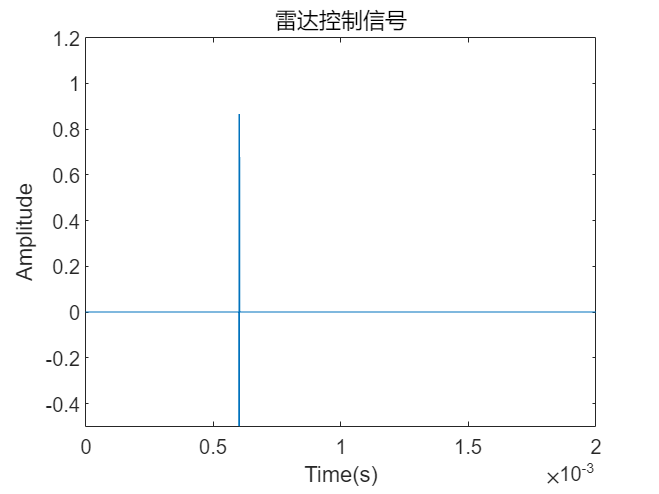

%参数设定
clock = 5*10^6;
clk=1/clock;
PRI=2*10^(-3);%定义雷达的PRI，根据雷达的最大探测距离来定义
tao=4*10^(-6);%定义雷达的脉冲宽度
N=1;%定义脉冲数
fs=1/clk;%采样频率
t1=6*10^(-4); %回波延迟
A=0; %脉冲幅度
P=20;%脉冲接受多少组做非相参积累
noise_amplitude=1;
t2=32*clk;%定义雷达保护单元
NZ=ceil(tao*fs);%卷积窗口的长度

%生成初始方波
t = linspace(0,N*PRI,N*fs*PRI); %定义时间长度
pulse=zeros(1,fs*PRI);%构建一个脉冲回波信号
pulse((ceil(t1*fs)+1):(ceil((t1+tao)*fs)))=sin(linspace(-3.1415926*3,3.1415926*3, length(pulse((ceil(t1*fs)+1):(ceil((t1+tao)*fs))))));
figure
plot(t(1:PRI*fs),pulse);
xlabel('Time(s)');
ylabel('Amplitude');
ylim([-0.5 1.2]);
title("雷达控制信号")

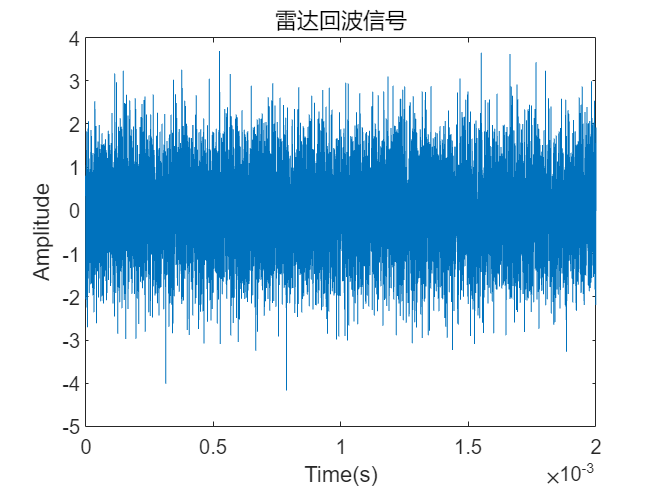


%根据所需要的脉冲数，构建雷达发射信号
Initial_pulse = repmat(pulse,P,N);%进行重组
Noise_pulse=Initial_pulse+noise_amplitude*randn(size(Initial_pulse));
% Noise_pulse=(Noise_pulse);
figure
plot(t,Noise_pulse(1,:));
xlabel('Time(s)');
ylabel('Amplitude');
xlim([0 max(t)]);
title("雷达回波信号")

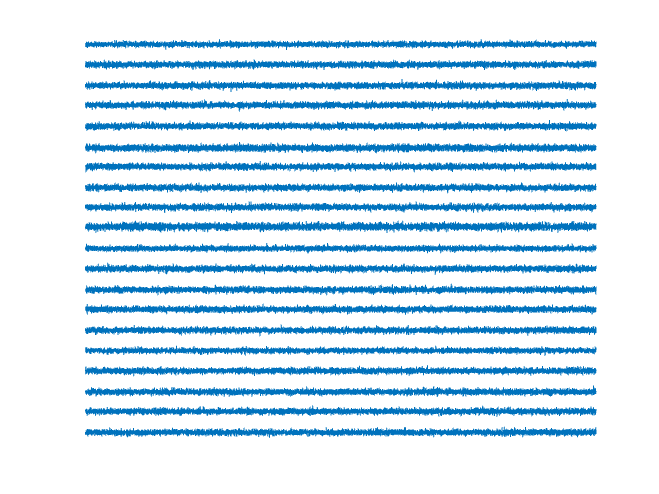


figure
for c=1:P
    subplot(P,1,c);
    plot(t,Noise_pulse(c,:));
    
    xlim([0 max(t)]);
    axis off
end

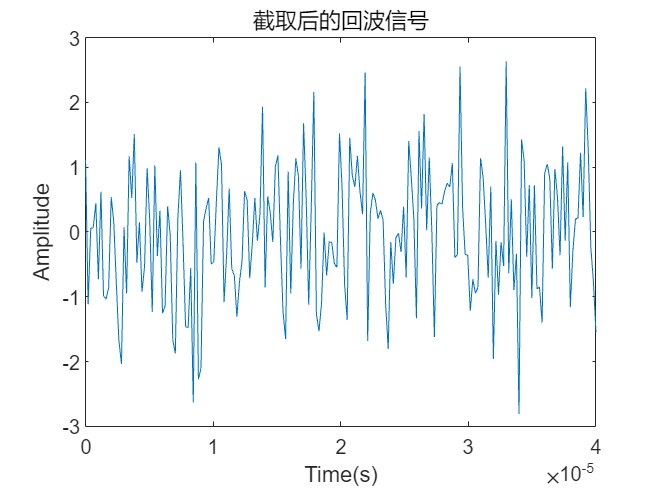


% 设置波门
gate_length = 10 * tao;  % 波门长度为2倍脉冲宽度
gate_samples = round(gate_length * fs);  % 波门长度对应的采样点数

% 截取回波信号
gate_start = round((t1-4*10^(-4)) * fs);  % 波门的起始采样点
gate_end = gate_start + gate_samples - 1;  % 波门的结束采样点

echo_signals = Noise_pulse(:, gate_start:gate_end);  % 截取回波信号

% 绘制截取后的回波信号
figure
t_gate = linspace(0, gate_length, gate_samples);  % 波门对应的时间轴
plot(t_gate, echo_signals(1, :))
xlabel('Time(s)')
ylabel('Amplitude')
title('截取后的回波信号')

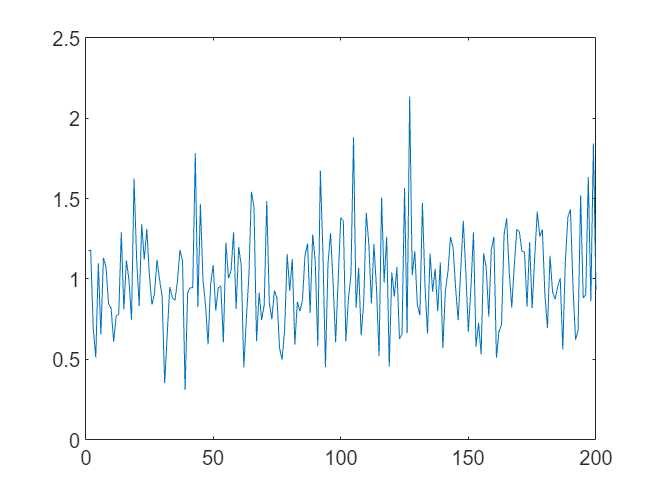


Noise_pulse = Noise_pulse(:, gate_start:gate_end);  % 截取回波信号




%非相参积累得到非相参后的信号

Nonnoncoherent_pulse=sum(Noise_pulse.^2,1)/P;%重构非相参积累公式,得到非相参信号
figure
% plot(t,Nonnoncoherent_pulse);
plot(Nonnoncoherent_pulse)

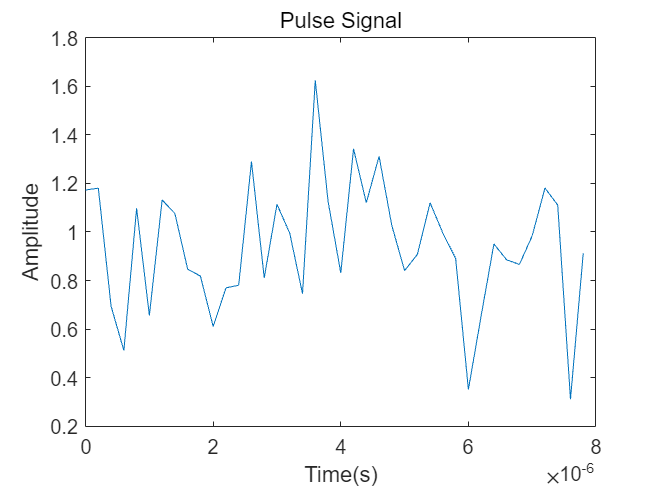


time = 40;

%计算阈值
final_pulse=Nonnoncoherent_pulse(1:time);%获取其中一组数据
figure%画出参考波形
plot(t(1:time),final_pulse(1:time));
xlabel('Time(s)');
ylabel('Amplitude');
% xlim([0 max(t)]);
title('Pulse Signal');

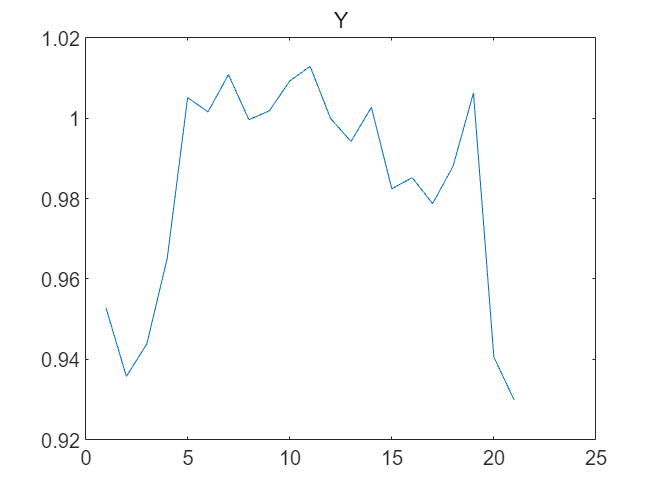

% square_pulse=final_pulse.*final_pulse;
a1=sum(final_pulse(1:ceil(t2*fs)))/length(final_pulse(1:ceil(t2*fs))); %左边窗口的阈值
a2=sum(final_pulse((time-ceil(t2*fs)):time))/length(final_pulse((time-ceil(t2*fs)):time));%右边窗口的阈值
threshold=1*max(a1,a2);%计算阈值
%循环求和目标检测
% 构造矩形窗口作为卷积核
h = ones(NZ, 1);

% 进行卷积运算并提取结果
y = conv(final_pulse, h,'valid')/NZ;

figure();
plot(y);
title('Y')

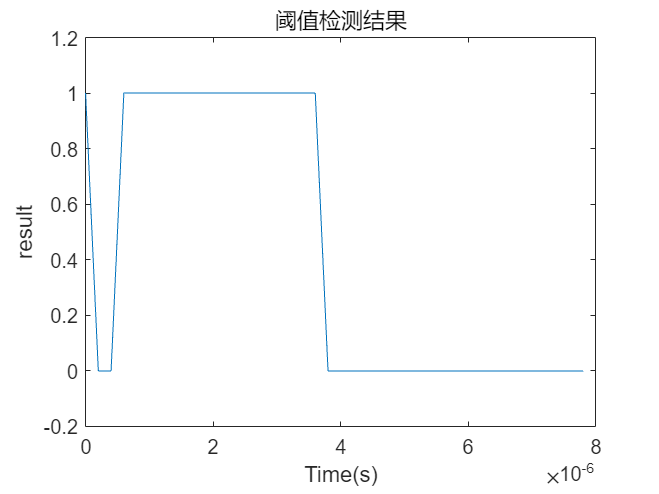


idx=find(y> threshold);

%显示结果
view=zeros(1,time);
view(idx)=1;
figure

plot(t(1:time),view(1:time));
ylim([-0.2 1.2]);
xlabel('Time(s)');
ylabel('result');
% xlim([0 max(t)]);
title('阈值检测结果');